# KINEMATIC ANALYSIS OF FOUR BAR MECHANISM

**IF LINK2 IS THE DRIVER**

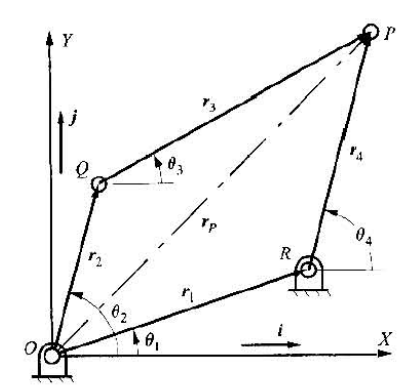

**GIVEN VALUES**

l1 = 100;
l2 = 45;
l3 = 55;
l4 =56;
theta_1 = 10;
theta_2 = 50;

**INITIAL CONDITIONS**

angle_3 = 15;
angle_4 = 60;
i=0;
sol =[angle_3,angle_4];

**POSITION ANALYSIS**

while i<1000
     f =[(l1*cos(theta_1) - l2*cos(theta_2) - l3*cos(sol(1)) + l4*cos(sol(2)));
         (l1*sin(theta_1) - l2*sin(theta_2) - l3*sin(sol(1)) + l4*sin(sol(2)))];

     df = [(l3*sin(sol(1))), (-l4*sin(sol(2)));
         (-l3*cos(sol(1))), (l4*cos(sol(2)))];

     sol = sol - (df\f);

     i =i + 1;
end

theta_3 = sol(1)

theta_3 = 9.5389

theta_4 = sol(2)

theta_4 = -18.0189

**VELOCITY ANALYSIS**


w2 = 12.5;
rAB = [l2*cos(theta_2) l2*sin(theta_2) 0]./1000;
rBC = [l3*cos(theta_3) l3*sin(theta_3) 0]./1000;
rDC = [l4*cos(theta_4) l4*sin(theta_4) 0]./1000;

k =[0 0 1];
V_P = w2*cross(k,rAB);
Vel_mag_P = norm(V_P)

Vel_mag_P = 0.5625


syms w3 w4


V_Q1 = V_P + w3*cross(k,rBC);
V_Q2 = w4*cross(k,rDC);

eqn_vel = V_Q1 - V_Q2 ==0;
S = solve(eqn_vel,[w3 w4]);

w3 = double(S.w3)

w3 = 13.8510

w4 = double(S.w4)

w4 = -5.6678


V_Q = double(subs(V_Q2,w4));
Vel_mag_Q = norm(V_Q)

Vel_mag_Q = 0.3174

**ACCELERATION ANALYSIS**

alpha_2 = -26;
a_P = alpha_2*cross(k,rAB) - ((w2^2)*rAB);
acc_mag_P = norm(a_P)

acc_mag_P = 7.1279


syms alpha_3 alpha_4

a_Q1 = a_B + alpha_3*cross(k,rBC) -((w3^2)*rBC);
a_Q2 = alpha_4*cross(k,rDC) -((w4^2)*rDC);

eqn_acc = a_Q1 -a_Q2 ==0;
R = solve(eqn_acc,[alpha_3 alpha_4]);

alpha3 = double(R.alpha_3)

alpha3 = 311.7019

alpha4 = double(R.alpha_4)

alpha4 = -197.7778


a_Q = double(subs(a_Q2,alpha4));
acc_mag_Q = norm(a_Q)

acc_mag_Q = 11.2207